# **Relay Control**

This example shows you how to setup the IO941-SPST-64 I/O module, in order to verify the basic functionality.

The IO941 is a relay module with up to 64 channels and various switch options, namely SPST, SPDT and DPST. The relays are either ruthenium reed relays, suitable for low level signals or electro-mechanical for higher voltages and currents.

The Simulink model features the [IO941 - Relay Control](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io94x_relay_control) block.

## Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with one IO941-SPST-64 I/O module installed

- Connector cable from the I/O module to the terminal board

- 50-pin terminal board

- Ohmmeter

### Test Setup

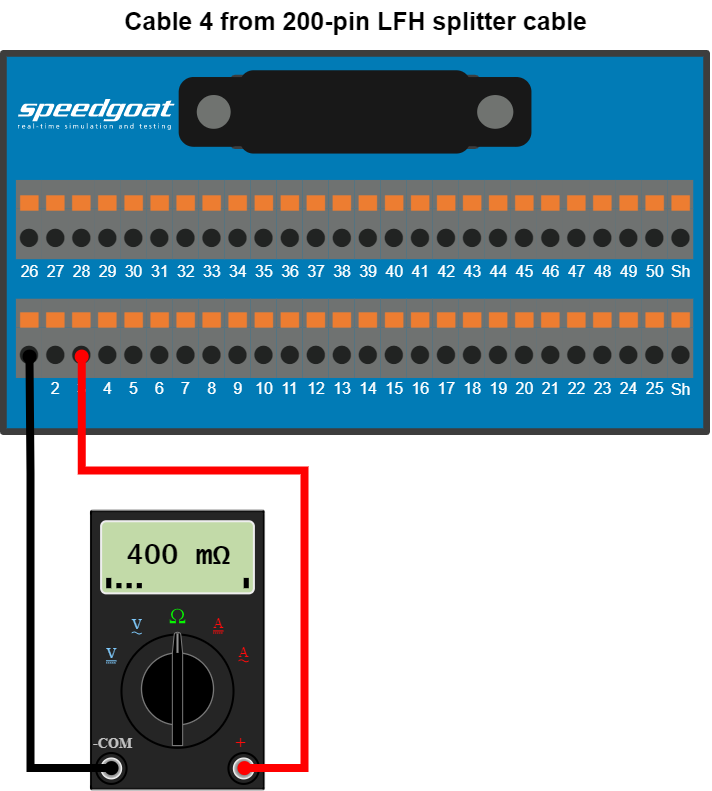

On the terminal board of the I/O module, connect an Ohmmeter to one of the two enabled channels to check their switch state as shown above. [IO941 Pin Mapping](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io94x_pin_mapping)

## Initialize and Open the Simulink model

 
% Open Simulink model
modelName = 'sgMdl_RelayControl';
open_system(modelName);

### Model Description

In the model, a pulse signal is used to toggle the relay of channel two every second. The relay of channel one is energized during the model run. Before this, it is set to the idle state (not energized) and reset to the initial state after the model run.

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Build the Simulink model
slbuild(modelName); % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName);

% Connect the Simulink model with external mode to the real-time application on the target machine
set_param(modelName, 'SimulationMode', 'external') % put model into External Mode
set_param(modelName, 'SimulationCommand', 'connect') % connect with External Mode

% Start the real-time application
tg.start;

% Wait a few seconds and then stop the real-time application on the target machine
pause(10)
tg.stop;

### Check the Results

To check if the relays have changed their state, check the connected scope. In the scope, a pulse signal must be displayed, and a straight line (represented by the yellow line).

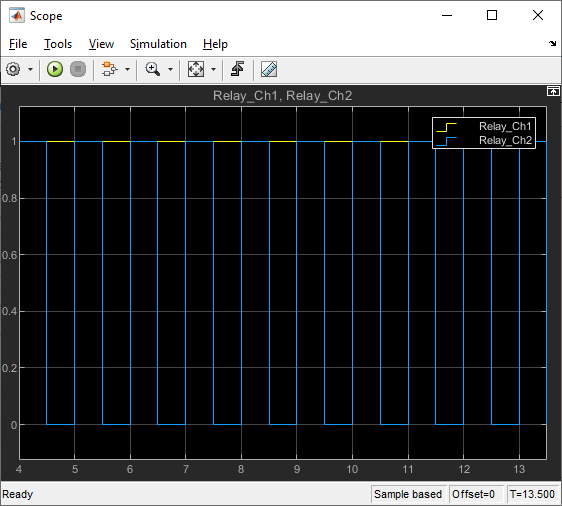

## Additional References

- [IO94x documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_io94x)